# Stride measurement of runner

# 画像からのランナーの歩幅の計測

This demo shows how to measure stride of runners from video. The process flow is the following:

- Human pose estimation by deep learning in every frame of video

- Correction of each joint positions detected

- Detections of footprint positions

- Projection of the coordinates from the frame to the actual world

- Calculation of the strides

[Japanese]このデモでは、動画で撮影したランナーの歩幅を計測します。処理の流れは下記のとおりです。

- ディープラーニングモデルを使って毎フレームの骨格検出

- 検出した各関節の位置を補正

- 足の接地点を検出

- 画像の座標から実空間の座標に投影変換

- 歩幅を計算

## Human pose estimation with deep learning model

## ディープラーニングモデルを使って毎フレームの骨格検出

% load video file
vr = VideoReader("VID_20200902_175939_crop.mp4");
% load pre-trained YOLOv3
YOLOv3mat = ['src',filesep,'YOLOv3', filesep, 'yolov3-416.mat'];
yolov3net = load(YOLOv3mat).("yolov3net");
% load detector for human pose
detector = posenet.PoseEstimator;

% video file for drawing the resulted pose
videoOutputFile = ['data', filesep, 'processed', filesep, 'overlay.mp4'];
vw = vision.VideoFileWriter(videoOutputFile);
vw.FileFormat = 'MPEG4';

% frames for processing
startFrame = 150;
endFrame = 300;
processFrameNum = endFrame - startFrame + 1;

% Variables for output
keypointsCell = cell(1,processFrameNum);
overlayFrames = cell(1,processFrameNum);

doInitialEstimates = false;
if doInitialEstimates % the calculation takes several minutes by CPU.
    for i = startFrame:endFrame
        frame = read(vr, i);
        %imshow(frame)
        [I, bboxes, scores, labels] = detect_w_PretrainedYOLOv3(frame, yolov3net);
        % if detected
        if ~isempty(bboxes) && nnz(labels == 1)
            bbox = bboxes(labels==1,:);
            bbox = bbox(1,:);
            % with a margin
            bbox(1:2) = bbox(1:2)- 50;
            bbox(3:4) = bbox(3:4) + 100;
            bbox(1) = max(bbox(1),1);
            bbox(2) = max(bbox(2),1);
            bbox(3) = min(vr.Width-bbox(1), bbox(3));
            bbox(4) = min(vr.Height-bbox(2), bbox(4));
            % crop and resize for Pose estimation network
            cropImg = frame(bbox(2):bbox(2)+bbox(4),bbox(1):bbox(1)+bbox(3),:);
            Iin = imresize(cropImg, detector.InputSize(1:2));
            
            % pose estimation
            keypoints = detectPose(detector,Iin);
            % calculate the coordinates in the original image
            keypoints_ord = originalCoord(keypoints, bbox, detector.InputSize(1:2));
            % draw
            K = detector.visualizeKeyPoints(frame, keypoints_ord);
            % output the results
            keypointsCell{i-startFrame+1} = keypoints_ord;
            vw(K);
            overlayFrames{i-startFrame+1} = K;    
        else % if no detection
            keypointsCell{i-startFrame+1} = nan(17,3);
            vw(frame);
            overlayFrames{i-startFrame+1} = frame;
        end
        
    end
    release(vw);
    % save the outputs
    resultFile = ['data', filesep, 'processed', filesep, 'results.mat'];
    save(resultFile, 'keypointsCell','overlayFrames');
end

### Check the outputs

### 得られた結果の確認

% load the outputs
resultFile = ['data', filesep, 'processed', filesep, 'results.mat'];
load(resultFile, 'keypointsCell','overlayFrames');
% convert to array
keypoints = cat(3,keypointsCell{:});
keypoints = permute(keypoints, [3 1 2]); % just for plotting without squeeze function
overlayFrames = cat(4, overlayFrames{:});
% extract frames including the detection
keypoints(isnan(keypoints)) = 0;
valIdx = find(sum(keypoints(:,:,3),2) > 0);
f1 = valIdx(1);
fend = valIdx(end);
% only for frames that include the detection
keypoints = keypoints(f1:fend,:,:);
overlayFrames = overlayFrames(:,:,:,f1:fend);

## Correction of the detected positions for each joints

## 検出した各関節の位置を補正

plot the Y-positions of left and right feet trajectory

[Japanese]右足、左足のY座標の軌跡の表示

figure;
plot(keypoints(:,end-1,2),'r.')
hold on;
plot(keypoints(:,end,2),'b.')
legend('left foot','right foot'); grid on; hold off;
axis ij;
title('History of Y-position')

Some values are not continous, which means mis-detection. It seems that the mis-detection occur when the feet overlap on the image.

[Japanese]不連続な結果となっている区間があり、誤検出していることがわかる。特に足が交差する際に、そのような誤検出が起きていると考えられます。

### Smoothing for Correction

### 平滑化による補正

data = keypoints(:,17,2);

% 入力データの平滑化
smoothedData = smoothdata(data,'rlowess','SmoothingFactor',0.04999999999999999);

% 結果の表示
clf
plot(data,'Color',[109 185 226]/255,'DisplayName','入力データ')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','平滑化済みのデータ')
hold off
legend

% Once the smoothing condition is fixed, apply those to all the joints
sm_keypoints = keypoints;
sm_keypoints(:,:,1) = smoothdata(keypoints(:,:,1), 1,'rloess','SmoothingFactor',0.1);
sm_keypoints(:,:,2) = smoothdata(keypoints(:,:,2), 1,'rloess','SmoothingFactor',0.1);
% visualization
imshow(overlayFrames(:,:,:,end));
hold on;
plot(sm_keypoints(:,16,1),sm_keypoints(:,16,2),'b.');
plot(sm_keypoints(:,17,1),sm_keypoints(:,17,2),'r.');
grid on; legend('left foot','right foot');
xlabel('X-position'); ylabel('Y-position');
title('Trajectory of the feet');

## Detection of footprints

## 足の接地点を検出

It is thought that the footprints corresponds to the local maxima of Y positions.

[Japanese]地面との接地点はY軸上での局所的極値になっている箇所と考えられますので、局所最大値のインデックスを求めることでこれらの時間を検出します。

isLMax_y = islocalmax(sm_keypoints(:,:,2),1);
footLeft = [sm_keypoints(isLMax_y(:,16),16,1), sm_keypoints(isLMax_y(:,16),16,2)];
footRight = [sm_keypoints(isLMax_y(:,17),17,1), sm_keypoints(isLMax_y(:,17),17,2)];
plot(footLeft(:,1), footLeft(:,2), 'go','MarkerFaceColor','blue', 'DisplayName', 'left footprint');
plot(footRight(:,1), footRight(:,2), 'yo','MarkerFaceColor','red', 'DisplayName','right footprint');
hold off

### Re-generate the video with the corrected trajectory and detected footprints

### 補正したkeypointsで動画を再作成

% frame numbers corrected
correctedFrames = startFrame + [f1:fend] -1;
% frame numbers corresponding to left footprints detected
footLeftFrames = startFrame + f1 + find(isLMax_y(:,16)) - 2;
% frame numbers corresponding to right footprints detected
footRightFrames = startFrame + f1 + find(isLMax_y(:,17)) - 2;

% invalid keypoints (out of the image)
keypoints_inval = sm_keypoints(:,:,1) < 1 | sm_keypoints(:,:,1) > vr.Width | ...
    sm_keypoints(:,:,2) < 1 | sm_keypoints(:,:,2) > vr.Height; 
sm_keypoints(:,:,3) = double(~keypoints_inval & logical(sm_keypoints(:,:,3)));
% re-permute the keypoints array to the original
psm_keypoints = permute(sm_keypoints, [2 3 1]);

% video file for drawing the results
videoOutputFile_comparison = ['data', filesep, 'processed', filesep, 'Comparison_before_after_correction.mp4'];
videoOutputFile_corrected = ['data', filesep, 'processed', filesep, 'overlay_corrected.mp4'];
vw = vision.VideoFileWriter(videoOutputFile_comparison);
vw.FileFormat = 'MPEG4';
vw2 = vision.VideoFileWriter(videoOutputFile_corrected);
vw2.FileFormat = 'MPEG4';

% if draw the corrected results to the video
drawCorrected = false;
if drawCorrected
    for i = startFrame:endFrame
        % i
        frame = read(vr, i);
        
        if any(ismember(correctedFrames, i))
            K_org = overlayFrames(:,:,:,i-correctedFrames(1)+1);
            K_org = insertText(K_org, [700 10], "Raw Detections", "FontSize", 28);
            K = detector.visualizeKeyPoints(frame, psm_keypoints(:,:,correctedFrames==i));
            cur_footLeft = footLeftFrames < i;
            cur_footRight = footRightFrames < i;
            K = insertShape(K,"Circle", [footLeft(cur_footLeft,1) footLeft(cur_footLeft,2) ones(nnz(cur_footLeft),1)*5],"Color",[0 200 0], "LineWidth", 4);
            K = insertShape(K,"Circle", [footRight(cur_footRight,1) footRight(cur_footRight,2) ones(nnz(cur_footRight),1)*5],"Color",[200 200 0], "LineWidth", 4);
            K = insertText(K, [700 10], "Corrected Detections", "FontSize", 28, "BoxColor", [200 0 0]);
            K = insertText(K, [730 60], "Left Footprint", "FontSize",18, "BoxColor", [0 200 0]);
            K = insertText(K, [730 100], "Right Footprint", "FontSize",18, "BoxColor", [200 200 0]);
        else
            K = frame;
            K_org = frame;
        end
        vw([K_org; K]);
        vw2(K);
    end
end
release(vw);
release(vw2);

## Transform from the image coordinates to the actual one

## 画像の座標から実空間の座標に投影変換

For this case, estimate the transformation matrix from the size of a gutter cover. The actual size of the cover is 46cm x 99.5cm.

[Japanese]今回は側溝の幅と長さから、投影のための変換行列を推定します。側溝の金属部分が実測46cm x 99.5㎝だったのでこの情報を使います。

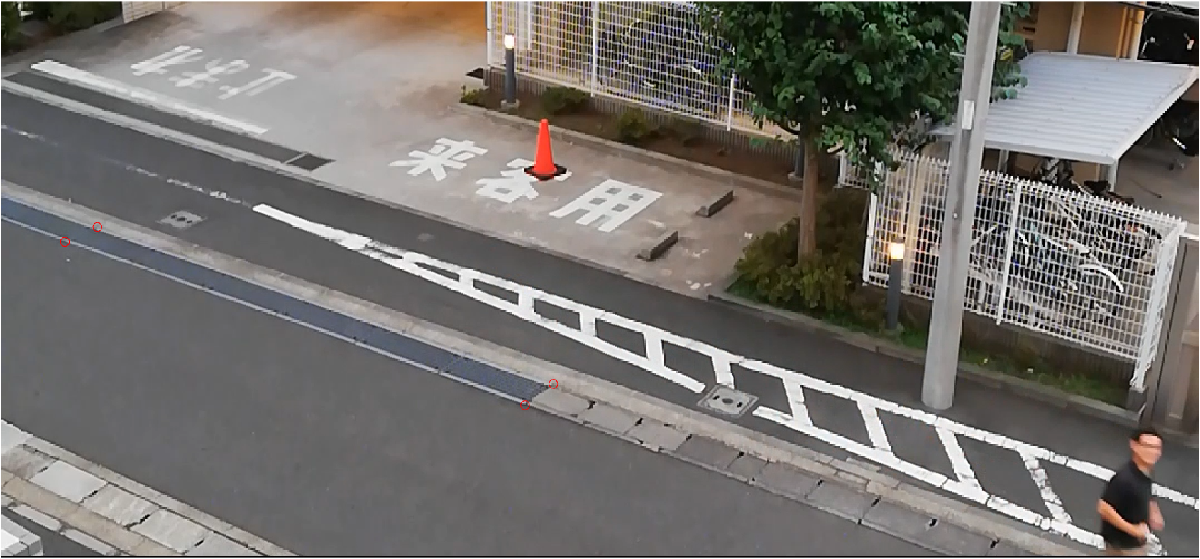f

 % the coordinates of the red circles in the image above（acquired by ginput)
 pts_img =[87.0914  204.1368;
   57.7836  217.4586;
  472.8896  365.0637;
  498.4674  345.8803];
% the actual coordinates(the origin is at the bottom-left)
pts_real = [0 0.46;
    0 0;
    6*0.995 0;
    6*0.995 0.46];
% Calculation of the transformation matrix
mytform = fitgeotrans(pts_img, pts_real, 'projective');
% Transform
[footLeftR_x, footLeftR_y] = transformPointsForward(mytform, footLeft(:,1), footLeft(:,2));
[footRightR_x, footRightR_y] = transformPointsForward(mytform, footRight(:,1), footRight(:,2));
footLeftR = [footLeftR_x footLeftR_y];
footRightR = [footRightR_x footRightR_y];

% Check
figure
plot(footLeftR(:,1), footLeftR(:,2), 'b.');
hold on;
plot(footRightR(:,1), footRightR(:,2), 'r.');
grid on; axis equal;

Exclude the last two steps, since they are out of the image.

[Japanese]動画から、最後の2歩はフレームアウトしており、正確な計測となっていないため、除外します。

footLeftR_lim = footLeftR(1:end-1,:);
footRightR_lim = footRightR(1:end-1,:);

### Rotate the coordinates so X-axis corresponds to the direction of proceeding

### 進行方向がX軸方向と合致するように座標変換（回転）する

p = polyfit([footLeftR_lim(:,1);footRightR_lim(:,1)],[footLeftR_lim(:,2);footRightR_lim(:,2)], 1); % get the tilt
drawX = [min(footLeftR_lim(1,1),footRightR_lim(1,1)):0.1:max(footLeftR_lim(end,1),footRightR_lim(end,1))];
plot(drawX,drawX*p(1)+p(2),'k-');
rot_angle = atan(p(1)); % tilt angle
rT = [cos(rot_angle) -sin(rot_angle); % rotation matrix
    sin(rot_angle) cos(rot_angle)];
% Correction
footLeftRcor = footLeftR_lim * rT;
footRightRcor = footRightR_lim * rT;

% check
figure
plot(footLeftRcor(:,1), footLeftRcor(:,2), 'b.', 'MarkerSize', 15);
hold on;
plot(footRightRcor(:,1), footRightRcor(:,2), 'r.', 'MarkerSize', 15);
grid on; axis equal;
xlabel('X(Direction of proceeding) [m]')
ylabel('Y [m]')
legend('Left footprint','Right footprint');

## Measure the stride

## 歩幅を計算

% average stride
if footLeftRcor(1,1) > footRightRcor(1,1) % the first is right foot
    footLR_x = zeros(length(footLeftRcor(:,1)) + length(footRightRcor(:,1)),1);
    footLR_x(1:2:end) = footRightRcor(:,1); % odd for right
    footLR_x(2:2:end) = footLeftRcor(:,1); % even for left
    stride = diff(footLR_x); % stride
    mean_stride = mean(stride);
    mean_stride_RL = mean(stride(1:2:end)); % the stride of left foot
    mean_stride_LR = mean(stride(2:2:end)); % the stride of right foot
else  % the first is left foot
    footLR_x = zeros(length(footLeftRcor(:,1)) + length(footRightRcor(:,1)),1);
    footLR_x(2:2:end) = footRightRcor(:,1); % even for right
    footLR_x(1:2:end) = footLeftRcor(:,1); % odd for left
    stride = diff(footLR_x); % stride
    mean_stride = mean(stride);
    mean_stride_RL = mean(stride(2:2:end)); % the stride of left foot
    mean_stride_LR = mean(stride(1:2:end)); % the stride of right foot
end

% visualize
figure
plot(stride, 'r.-');
title('History of the measured stride')
xlabel('Step Index')
ylabel('Stride [m]');
disp(sprintf('Average stride of right foot [m]: %f', mean_stride_LR))
disp(sprintf('Average stride of left foot [m]: %f', mean_stride_RL))
disp(sprintf('Average stride [m]: %f', mean_stride))

## Supporting function

function keypoints_ord = originalCoord(keypoints, cropCoord, detectImSize)
    scale_x = double(cropCoord(3)) / detectImSize(2);
    scale_y = double(cropCoord(4)) / detectImSize(1);
    keypoints_ord = double(keypoints);
    keypoints_ord(:,1) = keypoints(:,1) * scale_x + double(cropCoord(1))-1;
    keypoints_ord(:,2) = keypoints(:,2) * scale_y + double(cropCoord(2))-1;
end

Copyright 2020 The MathWorks, Inc.